## Create the Robot Model

ur5_RBT = loadrobot("universalUR5");
ur5_RBT.DataFormat = 'column';
q_home = [0 -90 0 -90 0 0]'*pi/180;
eeName = 'forearm_link';
T_home = getTransform(ur5_RBT, q_home, eeName);
T_home(1:4,4) = [0; 0; 0; 1];

## Visualize the robot at home configuration

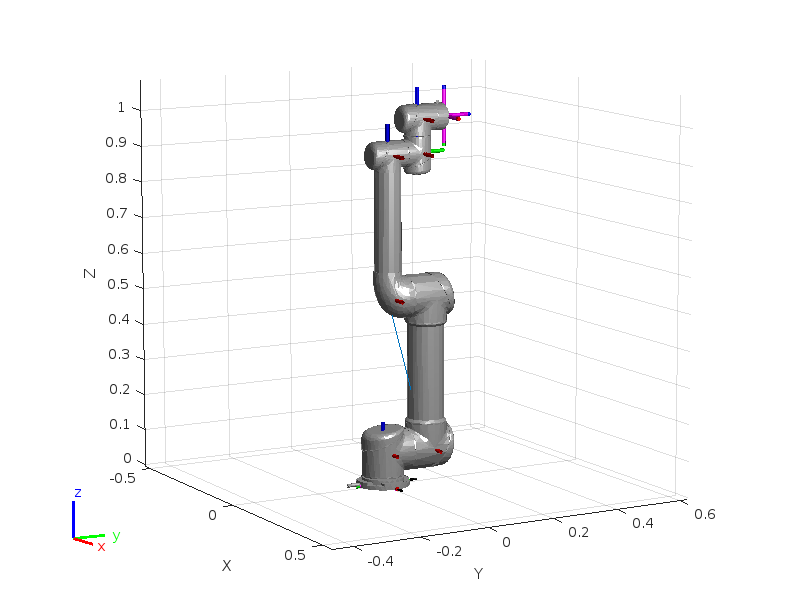

show(ur5_RBT,q_home);
axis auto;
view([60,10]); 

## Define a Set of Waypoints Based on the Tool Position

toolPositionHome = [0.455    0.001    0.434];
waypoints = toolPositionHome' + ... 
            [0 0 0 ; -0.2 0.2 0.2 ; -0.2 0 0.1 ; -0.1 -0.2 0.2 ; 0 0 0]';

Define orientation 

The orientation is represented in Euler angles and the convention used is the Tait-Bryan, extrinsic ZYX. 

orientations = [pi/2    0   pi/2;
               (pi/2)+(pi/4)      0   pi/2; 
                pi/2    0   pi;
               (pi/2)-(pi/4)       0    pi/2;
                pi/2    0   pi/2]';

Define array of waypoint times

waypointTimes = 0:7:28;
ts = 0.25;
trajTimes = 0:ts:waypointTimes(end);

Define boundary conditions for velocity and acceleration

waypointVels = 0.1 *[ 0  1  0;
                     -1  0  0;
                      0 -1  0;
                      1  0  0;
                      0	 1  0]';

waypointAccels = zeros(size(waypointVels));
waypointAccelTimes = diff(waypointTimes)/4;

## Create Inverse Kinematics Solver and Set Parameters

ik = inverseKinematics('RigidBodyTree',ur5_RBT);
ikWeights = [1 1 1 1 1 1];
ikInitGuess = q_home';
ikInitGuess(ikInitGuess > pi) = ikInitGuess(ikInitGuess > pi) - 2*pi;
ikInitGuess(ikInitGuess < -pi) = ikInitGuess(ikInitGuess < -pi) + 2*pi;

## Set Plot and Display Waypoints

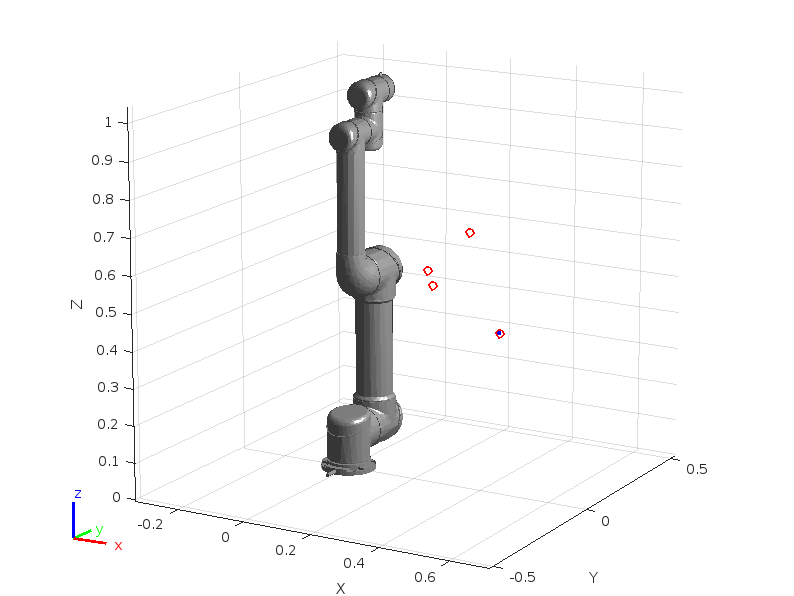

plotMode = 1; % 0 = None, 1 = Trajectory, 2 = Coordinate Frames
show(ur5_RBT,q_home,'Frames','off','PreservePlot',false);
hold on
if plotMode == 1
    hTraj = plot3(waypoints(1,1),waypoints(2,1),waypoints(3,1),'b.-');
end
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2);
axis auto;
view([30 15]);

## Solve the Inverse Kinematics for Each Waypoint

includeOrientation = true; 
numWaypoints = size(waypoints,2);
numJoints = numel(ur5_RBT.homeConfiguration);
jointWaypoints = zeros(numJoints,numWaypoints);
for idx = 1:numWaypoints
    if includeOrientation
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform(orientations(:,idx)');
    else
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform([pi/2 0 pi/2]); %#ok<UNRCH> 
    end
    [config,info] = ik(eeName,tgtPose,ikWeights',ikInitGuess');
    jointWaypoints(:,idx) = config';
end

## Generate a Trajectory in Joint Space using Interpolation

trajType = 'trap';
switch trajType
    case 'trap'
        [q,qd,qdd] = trapveltraj(jointWaypoints,numel(trajTimes), ...
            'AccelTime',repmat(waypointAccelTimes,[numJoints 1]), ... 
            'EndTime',repmat(diff(waypointTimes),[numJoints 1]));
                            
    case 'cubic'
        [q,qd,qdd] = cubicpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'quintic'
        [q,qd,qdd] = quinticpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints), ...
            'AccelerationBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'bspline'
        ctrlpoints = jointWaypoints; % Can adapt this as needed
        [q,qd,qdd] = bsplinepolytraj(ctrlpoints,waypointTimes([1 end]),trajTimes);
        % Remove the first velocity sample
        qd(:,1) = zeros (6,1);    
    otherwise
        error('Invalid trajectory type! Use ''trap'', ''cubic'', ''quintic'', or ''bspline''');
end

## Visualize the Solution

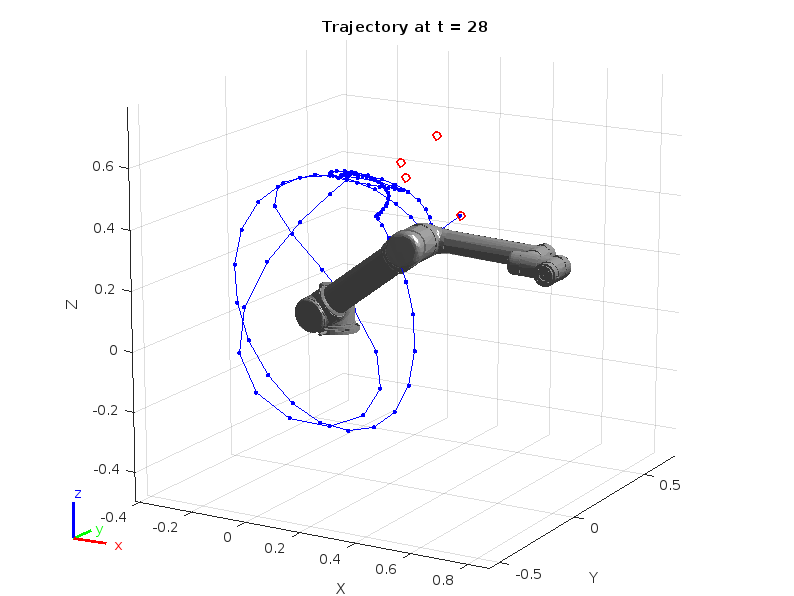

for idx = 1:numel(trajTimes)  
 
    config = q(:,idx)';
    
    % Find Cartesian points for visualization
    eeTform = getTransform(ur5_RBT,config',eeName);
    if plotMode == 1
        eePos = tform2trvec(eeTform);
        set(hTraj,'xdata',[hTraj.XData eePos(1)], ...
                  'ydata',[hTraj.YData eePos(2)], ...
                  'zdata',[hTraj.ZData eePos(3)]);
    elseif plotMode == 2
        plotTransforms(tform2trvec(eeTform),tform2quat(eeTform),'FrameSize',0.05);
    end
 
    % Show the robot
    show(ur5_RBT,config','Frames','off','PreservePlot',false);
    title(['Trajectory at t = ' num2str(trajTimes(idx))])
    drawnow   
    
end